clc
clear
model = createpde('structural','static-solid');
importGeometry(model,'strip.stl');

Display face labels

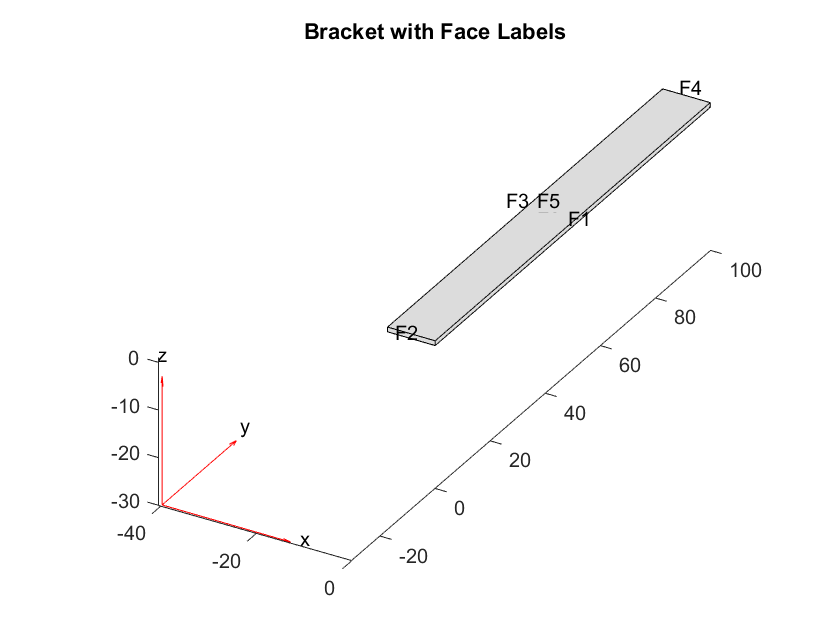

figure
pdegplot(model,'FaceLabels','on')
view(30,30);
title('Bracket with Face Labels')

Rear view

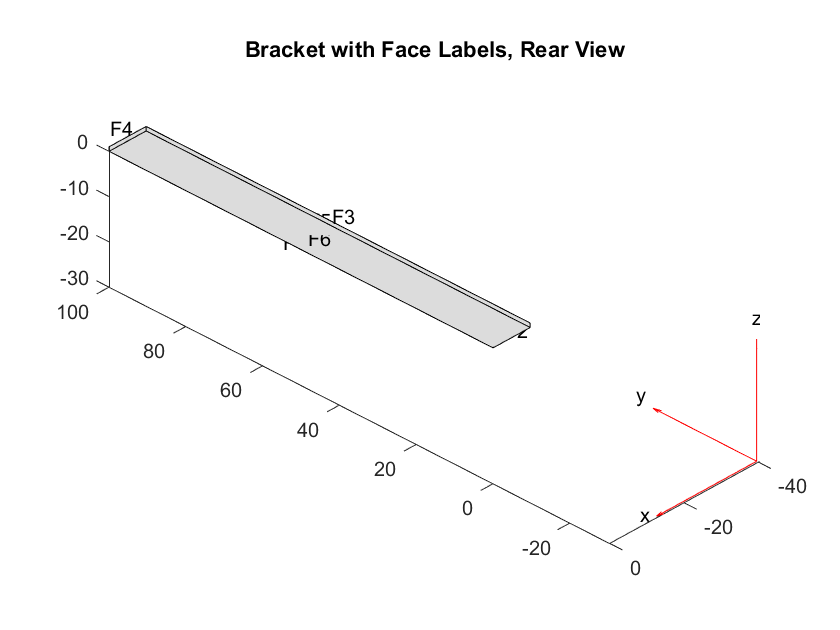

figure
pdegplot(model,'FaceLabels','on')
view(-134,-32)
title('Bracket with Face Labels, Rear View')

Structural Properties of Material

structuralProperties(model,'YoungsModulus',2.7e9, ...
                           'PoissonsRatio',0.3);

Two boundary conditions: the back face (face 4) is fixed, and the front face has an applied load. All other boundary conditions, by default, are free boundaries.

structuralBC(model,'Face',2,'Constraint','fixed');

Load

structuralBoundaryLoad (model,'Face',5,'SurfaceTraction',[0;0;-1e2]);

Mesh

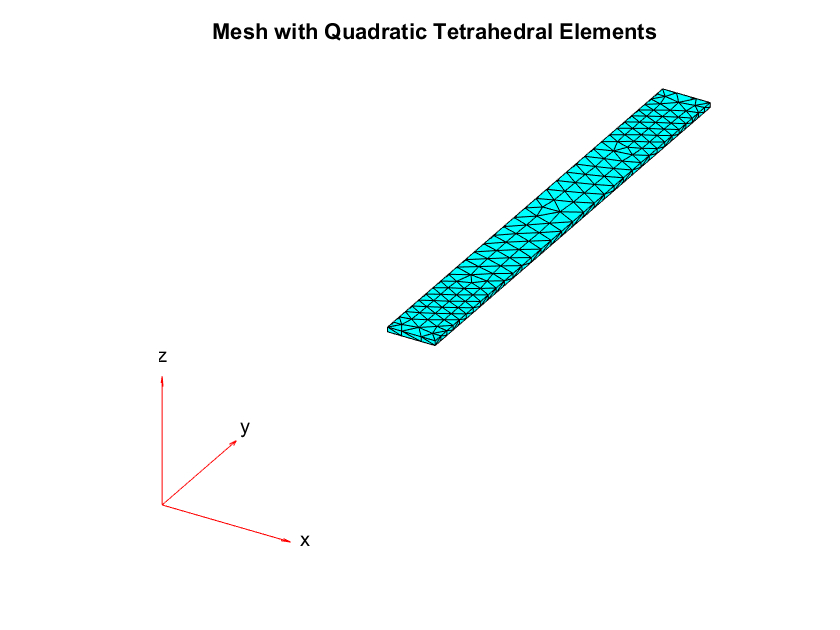

generateMesh(model);
figure
pdeplot3D(model)
title('Mesh with Quadratic Tetrahedral Elements');

Solution

result = solve(model)

result =   StaticStructuralResults with properties:

      Displacement: [1×1 FEStruct]
            Strain: [1×1 FEStruct]
            Stress: [1×1 FEStruct]
    VonMisesStress: [1737×1 double]
              Mesh: [1×1 FEMesh]


Find the maximal deflection

minUz = min(result.Displacement.uz);
fprintf('Maximal deflection in the z-direction is %g meters.', minUz)

Maximal deflection in the z-direction is -5.456 meters.

Plot the components of the solution

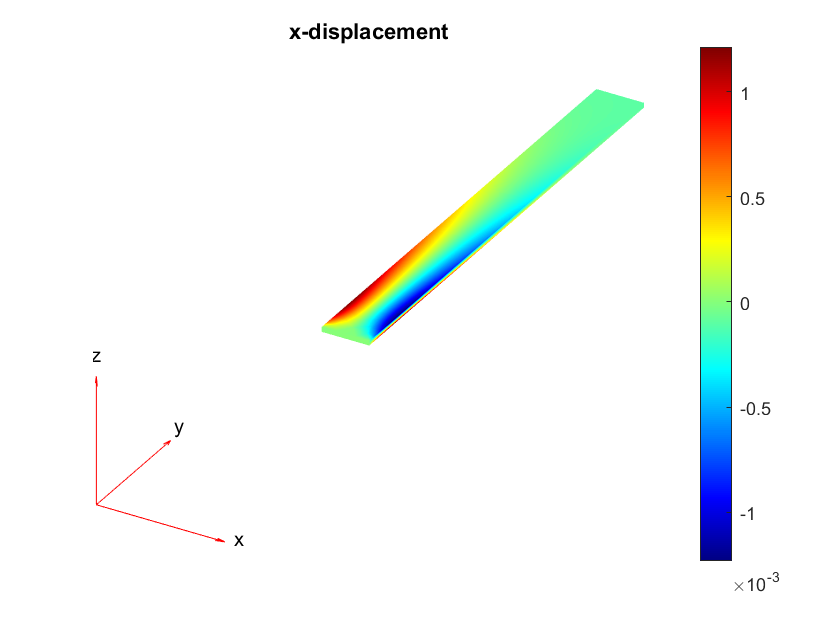

figure
pdeplot3D(model,'ColorMapData',result.Displacement.ux)
title('x-displacement')
colormap('jet')

Y

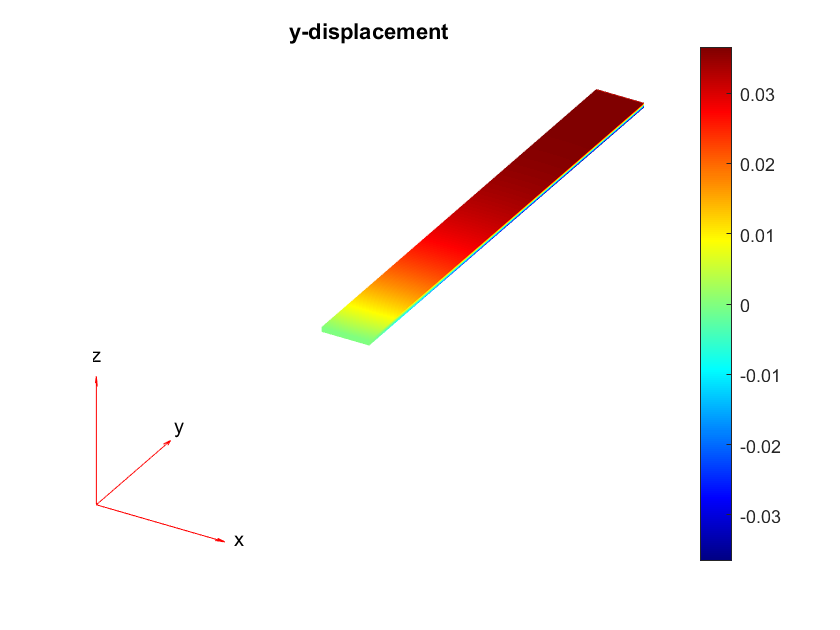

figure
pdeplot3D(model,'ColorMapData',result.Displacement.uy)
title('y-displacement')
colormap('jet')

Z

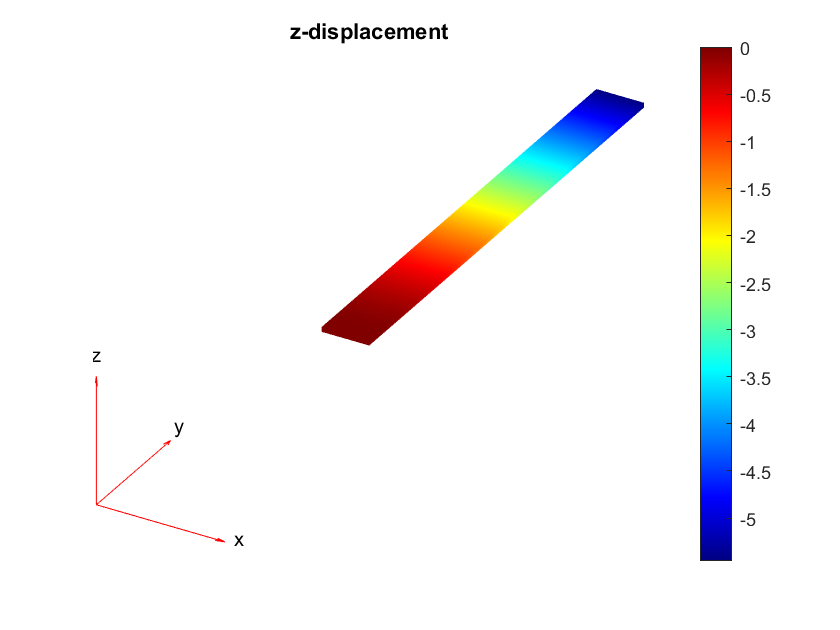

figure
pdeplot3D(model,'ColorMapData',result.Displacement.uz)
title('z-displacement')
colormap('jet')

Plot values of the von Mises stress at nodal locations

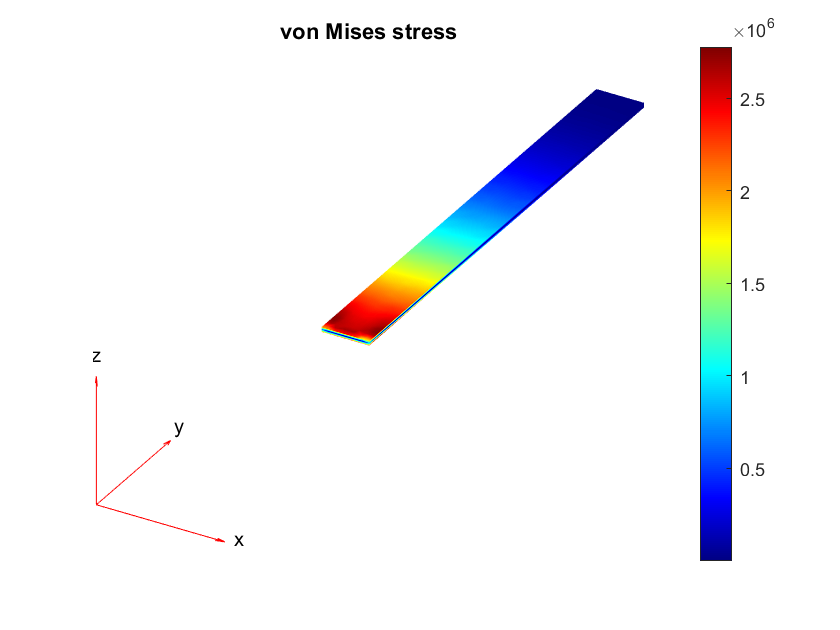

figure
pdeplot3D(model,'ColorMapData',result.VonMisesStress)
title('von Mises stress')
colormap('jet')